# Робот-манипулятор двухзвенный 

Выполнил: студент группы R4136c, Ларченков Артем

Цель работы: Оптимизация траектории робота с помощью генетического алгоритма.


$$reward = -\frac{ t^2}{1+|x| + |y| + |z|}$$


## Open the model with previous (initial) data

Open the open-chain model with settings for jumping behaviour

% % res_1_1 = 'optData_step_1_jump_15May23_2234.mat';
% % res_1_2 = 'optData_Ga15May23_2321.mat';
% % res_1_1 = 'optData_step_1_jump_1.mat';
% 
% % load(res_1_2)
% parameterss % model parameters
% mdlName = 'robott_old'; % main model
% open_system(mdlName); % open main model
% % jump = 1; run = 0; % option for jumping 
% sim_oc_jump = sim(mdlName,'StopTime','10','SrcWorkspace','current');
% measBody = get(sim_oc_jump.yout,'measBody').Values;
% 
% figure
% plot(measBody.X.Time, measBody.X.Data, ...
%      measBody.Y.Time, measBody.Y.Data, ...
%      measBody.Z.Time, measBody.Z.Data, ...
%     'linewidth', 1)
% grid on
% xlabel('$t$, [c]','Interpreter','latex')
% ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
% legend('y','z','x')

## Начальные данные для оптимизации

Определить количество точек траектории рабочего органа и начальные параметры

numPoints = 2;     
alpha = 0.08; % [rad]
gait_period = 0.40;

Создадим начальные условия для заполнения начальной популяции: (2 точки траектории, значение альфа, период прохода)

p0 = [zeros(1,numPoints) alpha gait_period]

p0 =          0         0    0.0800    0.4000


## Оптимизационные настройки для генетического алгоритма

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

opts = optimoptions('ga');
opts.Display = 'iter';
opts.MaxGenerations = 10;
opts.PopulationSize = 10;
opts.InitialPopulationMatrix = repmat(p0,[numPoints 1]); % Add copies of initial gait 
opts.PlotFcn = @gaplotbestf; % Add progress plot of fitness function
opts.UseParallel = false;

## Set constraints for trajectory points, alpha and gait period

upperBnd = [ 0.185*ones(1,numPoints), ...    % r max
             10*pi/4,...                      % alpha max
             0.50];                           % gait_period max
lowerBnd = [ 0.004*ones(1,numPoints), ...     % r min
             5*pi/4,...                      % alpha min
             0.40];                          % gait_period min

## Запуск

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html) function from Global Optimization Toolbox to optimize the walking gait, with **simulateOpenChainRobot** as the fitness function.

parameters % model parameters
mdlName = 'robott_20201_fin'; % main model


costFcn = @(p)optOpenChainmove(p,mdlName);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 10, Max Generations: 10



Single objective optimization:
4 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
    0.0040    0.0040    3.9270    0.4000

    0.1515    0.1786    7.0380    0.4392

    0.1679    0.0325    7.6949    0.4655

    0.0270    0.1797    6.5021    0.4171

    0.1693    0.1772    4.0672    0.4706

    0.1185    0.0919    7.2615    0.4032

    0.0217    0.1489    7.5948    0.4277

    0.0544    0.0297    6.5924    0.4046

    0.1030    0.0803    6.9026    0.4097

    0.1773    0.1697    6.8453    0.4823


                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    0.1679    0.0325    7.6949    0.4655

    0.1693    0.1772    4.0672    0.4655

    0.0040    0.0803    3.9270    0.4097

    0.1679    0.0325    7.6949    0.4655

    0.1185    0.0919    7.2615    0.4032

    0.1773    0.1489 

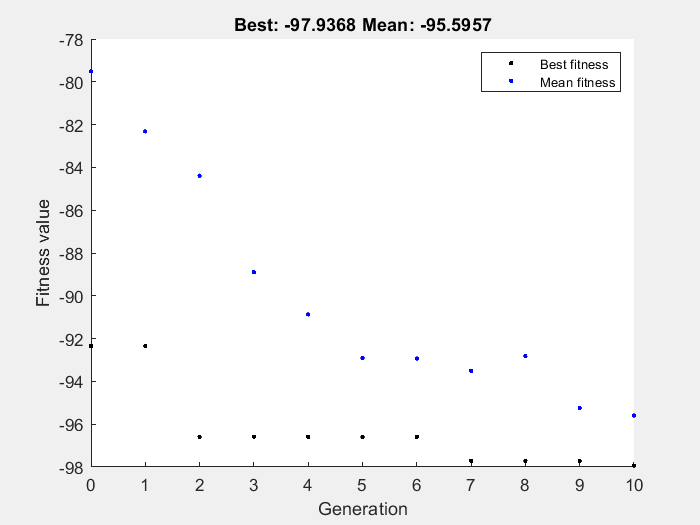

[pFinal,reward] = ga(costFcn,numPoints+2,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],[],opts);

disp(['Final reward function value: ' num2str(-reward)])

Final reward function value: 97.9368


## Analyze and save results

r_motion = [pFinal(1:numPoints) pFinal(1)];
alpha   = pFinal(numPoints+1)

alpha = 7.7701

gait_period = pFinal(numPoints+1+1)

gait_period = 0.4655

traj_times  = linspace(0,gait_period,numPoints+1);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
spln = createSpline(r_motion,gait_period,evalTimes);
r_der = createSmoothTrajectory(r_motion, gait_period);

Plot the resulting trajectory

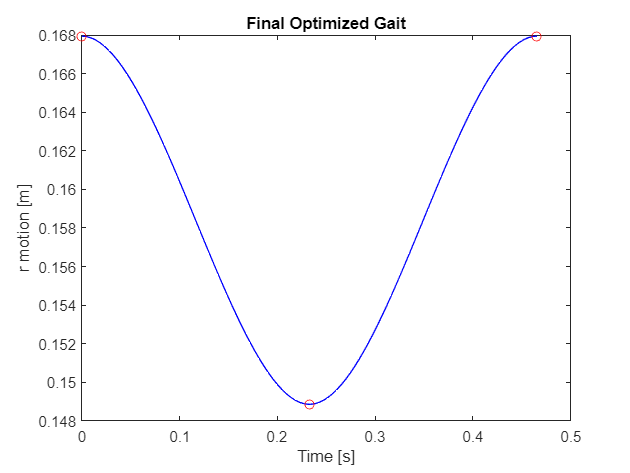

figure
plot(evalTimes,spln(1,:),'b-',traj_times,r_motion,'ro');
title('Final Optimized Gait');
xlabel('Time [s]');
ylabel('r motion [m]');

Save results to a timestamped MAT-file

outFileName = ['optData_Ga' datestr(now,'ddmmmyy_HHMM')];
save(outFileName,'reward','gait_period','traj_times','r_motion','alpha','r_der');

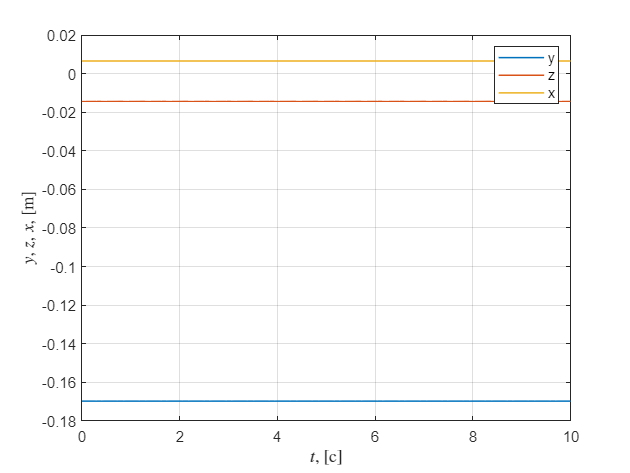

sim_traj = sim(mdlName,'StopTime','10','SrcWorkspace','current');
measBody = get(sim_traj.yout,'measBody').Values;

figure
plot(measBody.X.Time, measBody.X.Data, ...
     measBody.Y.Time, measBody.Y.Data, ...
     measBody.Z.Time, measBody.Z.Data, ...
    'linewidth', 1)
grid on
xlabel('$t$, [c]','Interpreter','latex')
ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
legend('y','z','x')